%Week 18 Worksheet - Numerically solving ODEs
%1)
clear all %required to ensure arrays clear each times

h=0.1; %declaring h
tf = 5; %final value of time (this value has been suggested by me)
t = 0:h:tf; %creating a range of values for t

%declaring initial conditions and starting x array 
%(varies with each question)
%x(1) = 1;
x(1) = 2;

mod(tf,h) %checking modulo for for loop condition

ans = 0


%running for loop
for i=1:tf/h
    
    %calculating each subsequent x term
    %(varies with each question)
    %x(i+1) = x(i) + h*(x(i)); 
    %x(i+1) = x(i) + h*(3 - x(i)); 
    x(i+1) = x(i) + h*(3*x(i) - x(i)^2);
    
end

plot(t,x,'.r') %plotting numerical solution

hold on %plotting on the same graph

syms T %declaring T as alternative to t array

%declaring analytical solution
%varies with question
%sol(T) = exp(T) 
%sol(T) = 3-exp(-T)
sol(T) = (6*exp(3*T))/(1 + 2*exp(3*T))

$$sol(T) = \frac{6\,{\mathrm{e}}^{3\,T}}{2\,{\mathrm{e}}^{3\,T}+1}$$

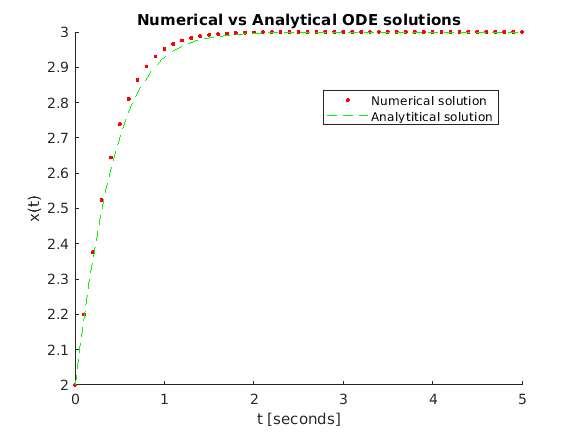


fplot(sol(T),[0 tf],"--g") %plotting analytical solution

hold off %end plotting

%beautifying
box off

%adding labels
title("Numerical vs Analytical ODE solutions")
xlabel("t [seconds]")
ylabel("x(t)")
legend("Numerical solution","Analytitical solution","Location","best")

%Solving second order ODE numerically
clear all %ensuring matrices are cleared

h = 0.02; %declaring size of incriments
tf = 50; %declaring maximum time
t = 0:h:tf; %declaring time array

%declaring initial conditions
%(these vary per question)
x(1) = 1

x = 1


%derivative
y(1) = 0

y = 0


mod(tf,h) %checking total time is divisible by time segments

ans = 0


%looping through time array
for i=1:tf/h
    
    %looping through steps
    x(i+1) = x(i) + h*y(i);
    
    %looping through derivative
    %(will vary perquestion)
    %y(i+1) = y(i) + h*(-3*y(i) -2*x(i));
    %y(i+1) = y(i) + h*(-2*y(i) - x(i));
    y(i+1) = y(i) + h*(-0.2*y(i) - 6*x(i));
end

syms T X(T) Y(T) %declaritng non array time

%finding analytical solution

%declaring ODE
%(these will vary with the question)
%ode = diff(X,T,2) + 3*diff(X,T) + 2*X == 0;
%ode = diff(X,T,2) + 2*diff(X,T) + X == 0;
ode = diff(X,T,2) + 0.2*diff(X,T) +6*X == 0;

%declaring initial conditions
Y(T) = diff(X,T) %equating y to my initial condition

$$Y(T) = \frac{\partial }{\partial T}X\left(T\right)$$


%the initial conditions can vary by question, however for this set of
%questions they are coincidentally all the same
IC = [X(0) == 1, Y(0)==0];

%solving ODE for particilar solution
sol(T) = dsolve(ode,IC)

$$sol(T) = \frac{{\mathrm{e}}^{-\frac{T}{10}}\,\left(599\,\cos\left(\frac{\sqrt{599}\,T}{10}\right)+\sqrt{599}\,\sin\left(\frac{\sqrt{599}\,T}{10}\right)\right)}{599}$$

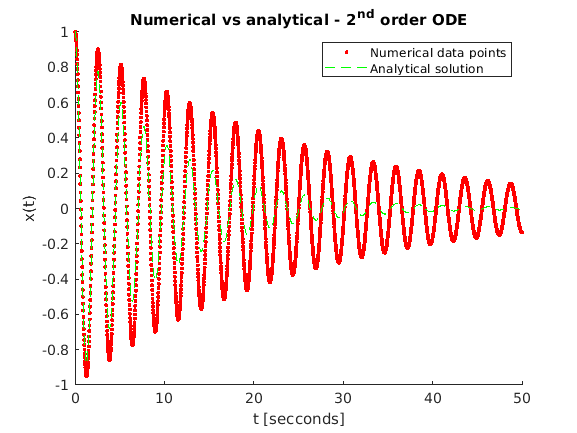


%plotting numerical solution
plot(t,x,".r")

hold on %plotting on the same graph

%plotting analytical solution
fplot(sol(T),"--g",[0 tf])

hold off %end plotting

%labelling plot
title("Numerical vs analytical - 2^{nd} order ODE")
xlabel("t [secconds]")
ylabel("x(t)")
legend("Numerical data points","Analytical solution")

%beautifying
box off